In this file we plot the two neccessary coordinates i.e. tr(\zeta) and det(A) in order to determine when impacts happen for the matrix groups example

j = 1

j = 1

j = 1

j = 1

j = 1

j = 1

j = 1

j = 1

j = 1

j = 1

j = 1

IC =      0     2


j = 1

IC =      0     2


j = 1

IC =      0     2


j = 1

IC =      0     2


j = 1

IC =      0     2


j = 1

IC =      0     2


j = 1

IC =      0     2


j = 1

IC =      0     2


j = 1

IC =      0     2


j = 1

IC =      0     2


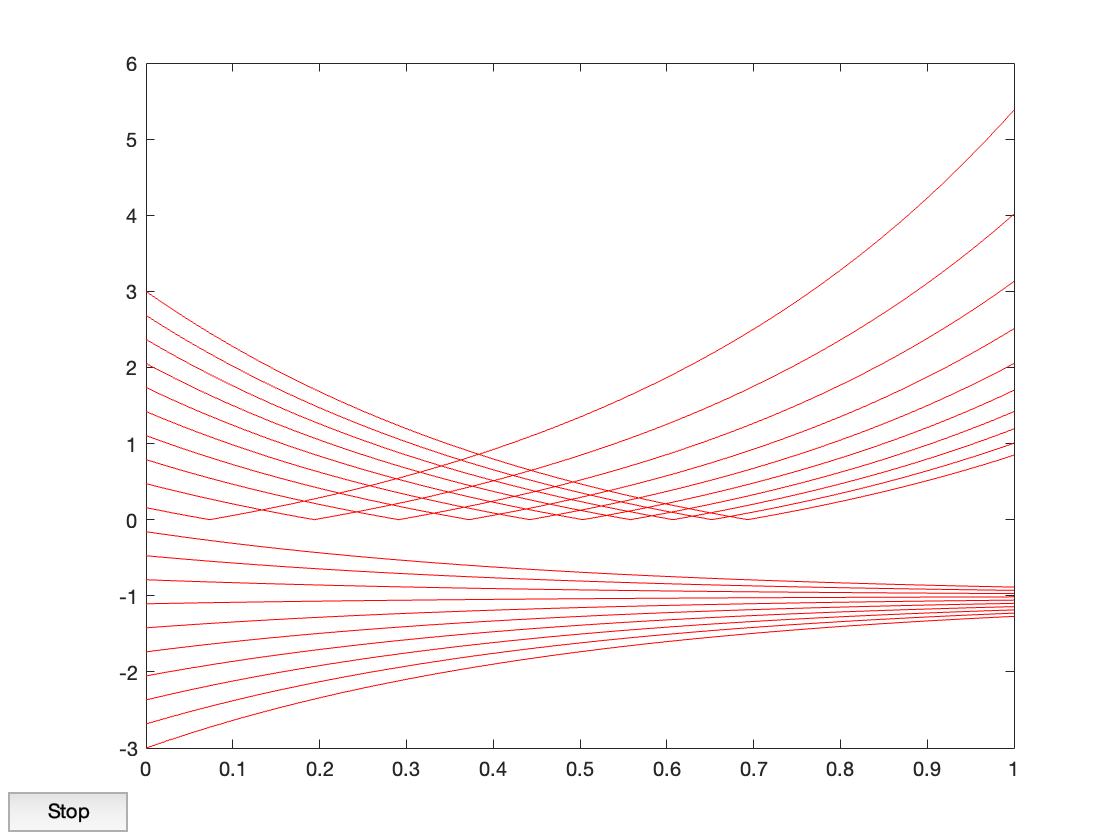

N = 20;
q0 = linspace(-3, 3, N);
C0 = linspace(-2, 2, N);
x_now = [1 -1];
T = 1;
%opt = odeset('Events', impact, 'OutputFcn',@odephas2);
opts = odeset('Events', @impact, 'OutputFcn',@odeplot ,'OutputSel', 1);
   
for i = 1:N
   % for j = 1:N
   j = 1
        x_now = [q0(i) C0(j)];
        [t, y] = ode45(@eom, [0, T], x_now, opts);           
        % apply the reset map
        IC = y(end, :);
        t = t(end);
        hold on
        
        while t < T
                IC = reset(IC)
                [t, y] = ode45(@eom, [t, T], IC, opts);
                IC = y(end, :);            
                t = t(end); 
                hold on;
        end     
   % end
end

hlines = findall(gca,'type','line','marker','o')

hlines =   0×0 empty GraphicsPlaceholder array.


% change the marker type to none or some other shape
set(hlines(:),'marker','none', 'color', 'red')
%set(hlines(:),'Color', 'red')

%hlines = findall(gca, 'type', 'line')
%set(hlines(:), 'Color', 'blue')

function dydt = eom(t, y)

    dydt = zeros(size(y));
    dydt(2) = 0;
    dydt(1) = (y(1) + 1)*y(2);
end
function [position,isterminal,direction] = impact(t, y)
     position = y(1);
     isterminal = 1;
     direction = 0;
end

function y_plus = reset(y_minus)
    y_plus = y_minus.*[0 -1];
end